23 de febrero del 2022.

[GitHub](https://github.com/jdrengifoc/Stochastic-Process/)

**Nota:** Se sugiere mirar el livescript en formato `.mlx` puesto que hay contenido interactivo.

# Taller de Seguimiento 2

Procesos estocásticos CM0433

**Nombre: ** Juan David Rengifo Castro.

**Código: **201810011101.

## Problema

En la data se registraron la hora que fueron atendidos $106$ pacientes de un hospital. ¿Existe evidencia suficiente para decir que los pacientes llegan según un proceso de Poisson? ¿Cuál es la intensidad del proceso?

## Preliminares.

Recordemos que un proceso de poisson es un** proceso de conteo** que cumple con ciertas características. Su definición puede ser axiomática, descriptiva o constructiva. Por motivos de simplicidad, usaremos verificaremos si los datos siguen un proceso de Poisson usando la definición **constructiva **que se presenta a continuación. Pero antes, definamos conceptos de interés.

**Proceso de Poisson (Def. Constructiva). **Sean $t_1, ..., t_n$ variables aleatorias independientes que distribuyen $exp(\lambda)$. Sea $T_n = t_1 + ... + t_n$ el tiempo hasta el evento $n$ y $T_0 = 0$, entonces el proceso de conteo $N(s) = max\{n: T_n \leq s \}$ es un proceso de poisson con intensidad $\lambda$.

## Solución

Comenzamos importanto los datos de manera apropiada y definimos tres vectores: horas entre eventos $(t)$, horas hasta el evento $n$ $(T)$ y el número de eventos $N$. Sean $t_0 = 0$ un tiempo menor a la hora del primer evento, entonces es claro que $N(0) = 0$.

data = datetime(datestr(xlsread('Taller 2.xlsx'), 'HH:MM:SS AM'));
t = diff(data);
T = cumsum(inter_time);
N = (1:length(inter_time))';
process = [N, hours(t), hours(T)];

Veamos ahora si los tiempos entre llegadas distribuyen exponencial, para esto emplearemos un análisis gráfico y pruebas de hipótesis.

Las pruebas de hipótesis que usamos son:

- La prueba no paramétrica para dos muestras de  [Kolmogorov-Smirnov](https://la.mathworks.com/help/stats/kstest2.html) (KS), la cual tiene como hipótesis nula que dos conjuntos de datos provienen de la misma distribución.

- La prueba no paramétrica para dos muestras de [Ansari-Bradley](https://la.mathworks.com/help/stats/ansaribradley.html) (AB), la cual tiene como hipótesis nula que dos conjuntos de datos provienen de la misma distribución.

- La prueba de suma de [rangos de Wilcoxon](https://la.mathworks.com/help/stats/ranksum.html) (RW), la cual tiene como hipótesis nula que dos conjuntos de datos son muestras de distribuciones continuas con medianas idénticas.

Comenzamos estimando los parámetros del proceso generador de datos, si este distribuye exponencial. Para esto usamos la función [`fitdist.M`](https://la.mathworks.com/help/stats/fitdist.html), la cual nos retorna la estimación de la media $(\mu)$ con su respectivo intervalo de confianza. Es decir, la tasa de la distribución exponencial es $\lambda = \mu^{-1} = 4.4552$. Con estas estimaciones procedemos a simular $100$ datos, cada uno$10000$ observaciones exponenciales independientes y realizamos las pruebas KS, AB y RW para un nivel de significancia de $\alpha = 0.01$. Como se muestra a continuación, en ningun caso, se rechaza la hipótesis nula de que los datos vienen de la misma distribución, pero si lo hacen todos los test si usamos otra distribución como una normal o uniforme. Por lo tanto, todo parece indicar que los tiempos entre llegada de los datos son independientes y exponenciales.

% Estimate the parameters of interarrival times.
pd = fitdist(hours(t),'exponential')

pd =   ExponentialDistribution

  Exponential distribution
    mu = 0.224458   [0.187028, 0.274431]


lamda = 1 / pd.mu

lamda = 4.4552

% Non-parametric hypotesis test.
sample_size = 100; n_test = 100; alpha = 0.01;
h = nan(n_test, 3);
for i = 1:n_test
    h(i, 1) = kstest2(hours(t), exprnd(pd.mu, sample_size, 1), 'Alpha', alpha);
    [~, h(i, 2)] = ranksum(hours(t), exprnd(pd.mu, sample_size, 1), 'alpha', alpha);
    [h(i, 3), ~, ~] = ansaribradley(hours(t), exprnd(pd.mu, sample_size, 1), "Alpha", alpha);
end
disp('No rechaza para la distribución exponencial.')

No rechaza para la distribución exponencial.


sum(h)

ans =      0     0     1



% Otras distribuciones.
disp('Rechaza para otras distribuciones')

Rechaza para otras distribuciones


[~, aux] = ranksum(hours(t), rand(10000, 1))

aux = logical
   1


ansaribradley(hours(t), rand(10000, 1))

ans = 1

[~, aux] = ranksum(hours(t), randn(10000, 1))

aux = logical
   1


ansaribradley(hours(t), randn(10000, 1))

ans = 1

kstest2(hours(t), randn(10000, 1))

ans = logical
   1


kstest2(hours(t), rand(10000, 1))

ans = logical
   1


Posteriror a esto, graficamos la función de distribución acumulada empírica de los datos contra la exponencial y vemos que son muy similares, por lo tanto, no hemos encontrado evidencia en contra de que los tiempos entre eveentos sean independientes y exponenciales, por lo tanto, concluimos que si lo son.

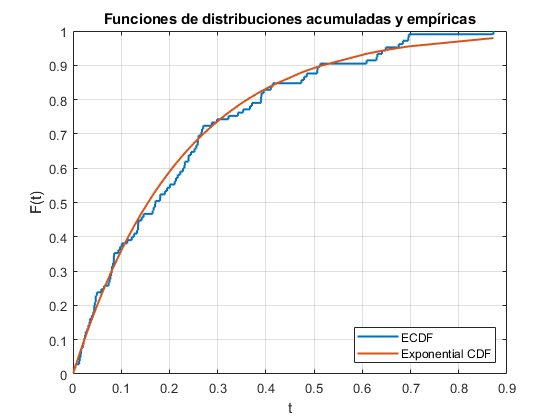

[X, F] = ECDF(hours(t));
[F_real] = expcdf(X, pd.mu);
plot(X, F, X, F_real, 'Linewidth', 1.5)
grid on
legend({'ECDF', 'Exponential CDF'}, 'Location','SE')
xlabel('t'); ylabel('F(t)')
title('Funciones de distribuciones acumuladas y empíricas')

Así las cosas, sea $T_n = t_1 + ... + t_n$ es las horas hasta la llegada del paciente $n$, entonces el proceso de conteo $N(s) = max\{n: T_n \leq s \}$asociado a nuestros datos parece ser un proceso de Poisson con intensidad $\lambda = \mu^{-1} = 4.4552 \frac{\text{pacientes}}{\text{hora}}$.

## Funciones

function [X,F] = ECDF(vec)
X = sort(unique(vec));
X = reshape(X,[],1);
F = zeros(length(X),1);

for i = 1:length(X)
    F(i) = sum(vec <= X(i))/length(vec);
end

for i = 2:2:2*length(X)-1
    F = [F(1:i-1);F(i-1);F(i:end)];
    X = [X(1:i-1);X(i);X(i:end)];
end
end

% Wilcoxon para una matriz. Test de rango para determinar si los datos
% provienen de una misma distribución.
% H0: misma distribución
% H1: diferente distribución
function S = rankTest(data,varargin)
if nargin > 1
    [varargin{:}] = convertStringsToChars(varargin{:});
end

try
    pnames = {'alpha','tail'};
    dflts  = {0.05,'both'};
    [alpha,tail] = internal.stats.parseArgs(pnames,dflts,varargin{:});
catch
    error('Wrong Input Arguments')
end
% Check alpha
if ~isa(alpha,'double')
    alpha = 0.05;
    warning('Wrong alpha. Modified to default (0.05.')
    
elseif 0 >= alpha || alpha >= 1
    alpha = 0.05;
    warning('Wrong alpha. Modified to default (0.05.')
end

% check tail
validTails = ["both","right","left"];
tail = char(validatestring(tail,validTails));

S = struct();
[~,p] = size(data);
p_vals = nan(p,p);
for j = 1:p
    for i = 1:p
        x = data(:,j);
        y = data(:,i);
        p_vals(i,j) = ranksum(x,y,'tail',tail);
    end
end
h = p_vals <= alpha;
S.p = p_vals;
S.h = h;
[fil,col] = find(h);
S.idx = [fil(1:length(fil)/2),col(1:length(col)/2)];
S.stats = {'alpha',alpha;'tail',tail};
end